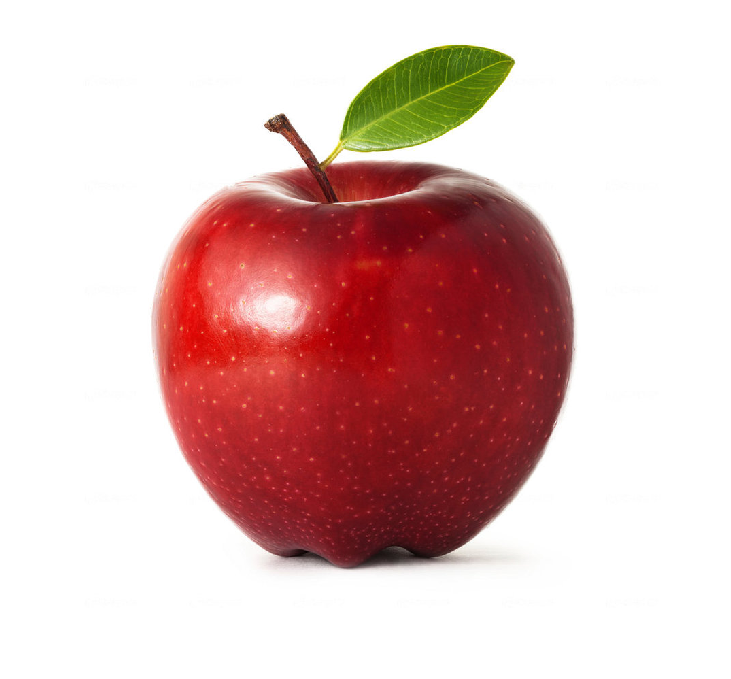

I = imread('buah\buah1.jpg');
figure, imshow(I);

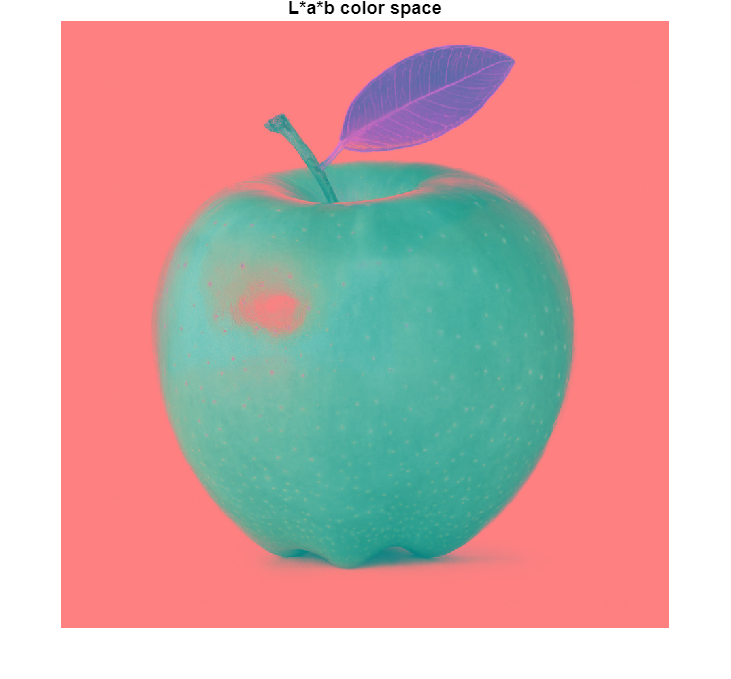

% Color-Based Segmentation Using K-Means Clustering
cform = makecform('srgb2lab');
lab = applycform(I,cform);
figure, imshow(lab), title('L*a*b color space');

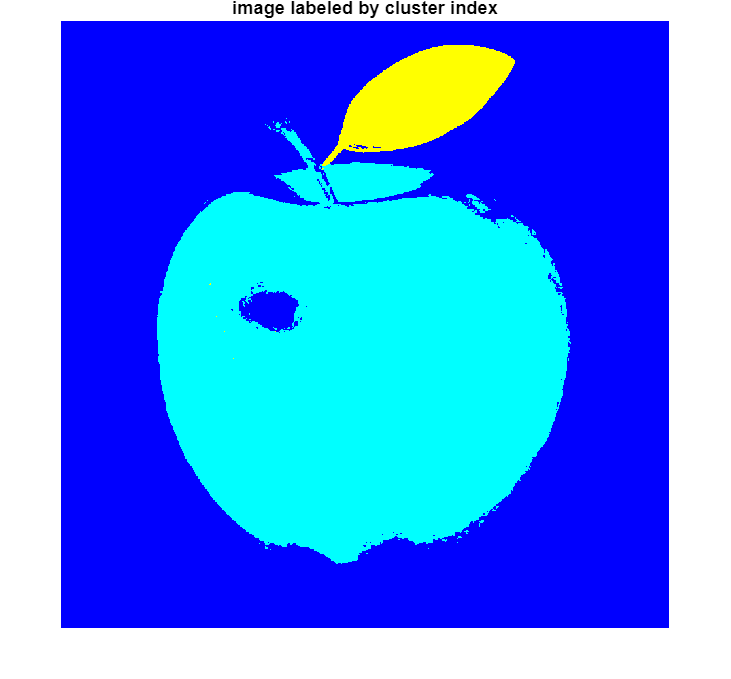

ab = double(lab(:,:,2:3));
nrows = size(ab,1);
ncols = size(ab,2);
ab = reshape(ab,nrows*ncols,2);
 
nColors = 3;
[cluster_idx, cluster_center] = kmeans(ab,nColors,'distance','sqEuclidean', ...
                                      'Replicates',3);
 
pixel_labels = reshape(cluster_idx,nrows,ncols);
RGB = label2rgb(pixel_labels);
figure, imshow(RGB,[]), title('image labeled by cluster index');

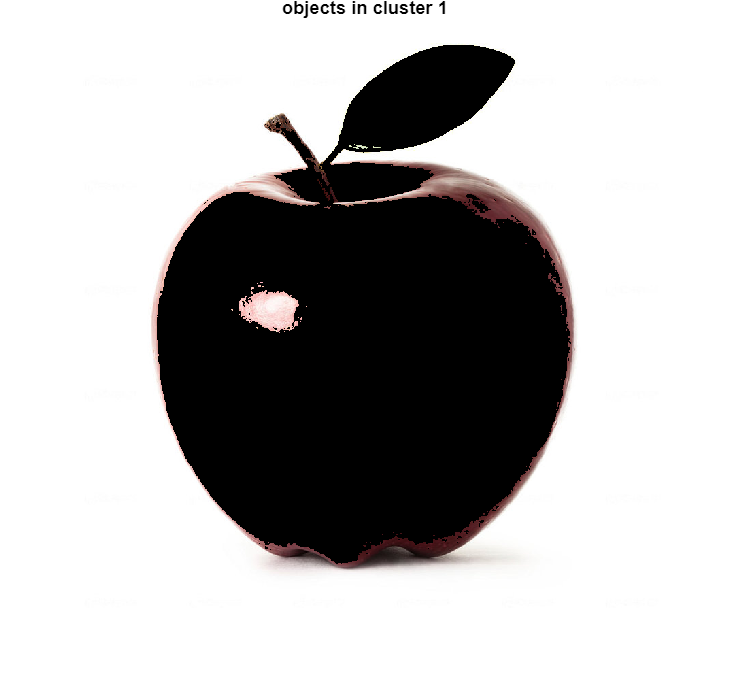

segmented_images = cell(1,3);
rgb_label = repmat(pixel_labels,[1 1 3]);
 
for k = 1:nColors
    color = I;
    color(rgb_label ~= k) = 0;
    segmented_images{k} = color;
end
 
figure,imshow(segmented_images{1}), title('objects in cluster 1');

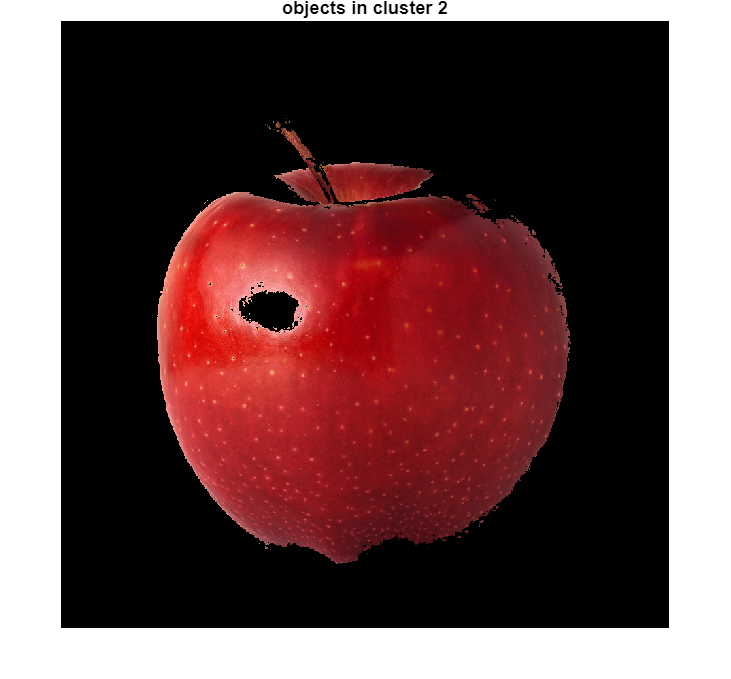

figure,imshow(segmented_images{2}), title('objects in cluster 2');

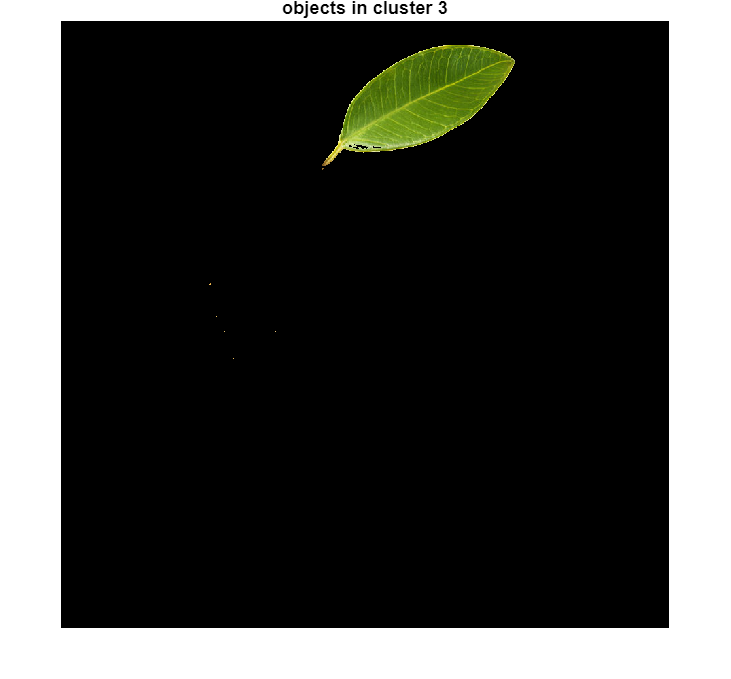

figure,imshow(segmented_images{3}), title('objects in cluster 3');

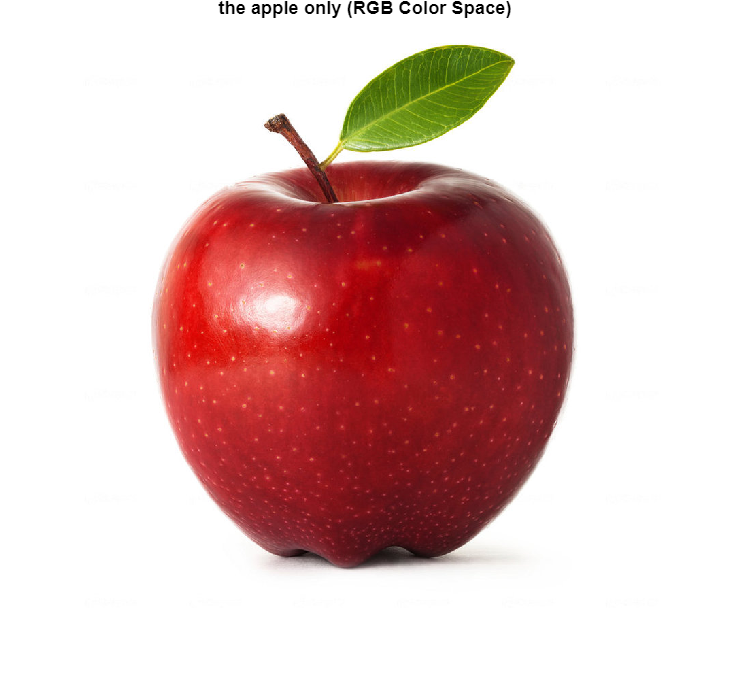

% segmentation
area_cluster1 = sum(sum(pixel_labels==1));
area_cluster2 = sum(sum(pixel_labels==2));
area_cluster3 = sum(sum(pixel_labels==3));
 
[~,cluster_apel] = min([area_cluster1]);
apel_bw = (pixel_labels==cluster_apel);
apel_bw = imfill(apel_bw,'holes');
apel_bw = bwareaopen(apel_bw,1000);
 
apel = I;
R = apel(:,:,1);
G = apel(:,:,2);
B = apel(:,:,3);
R(~apel_bw) = 0;
G(~apel_bw) = 0;
B(~apel_bw) = 0;
apel_rgb = cat(3,R,G,B);
figure, imshow(apel_rgb), title('the apple only (RGB Color Space)');

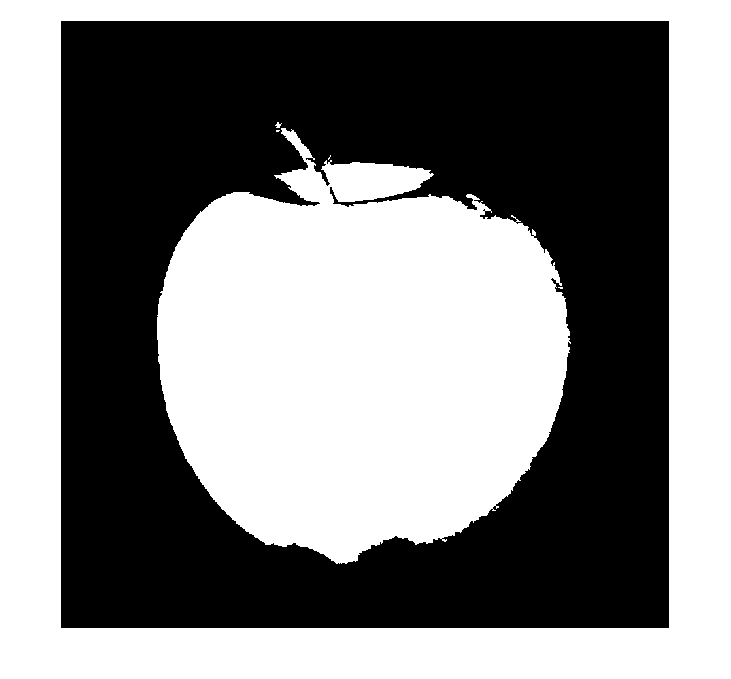

% Final Test
% Color-Based Segmentation Using K-Means Clustering
    cform = makecform('srgb2lab');
    lab = applycform(I,cform);
 
    ab = double(lab(:,:,2:3));
    nrows = size(ab,1);
    ncols = size(ab,2);
    ab = reshape(ab,nrows*ncols,2);
 
    nColors = 2;
    [cluster_idx, ~] = kmeans(ab,nColors,'distance','sqEuclidean', ...
        'Replicates',3);
 
    pixel_labels = reshape(cluster_idx,nrows,ncols);
 
    segmented_images = cell(1,3);
    rgb_label = repmat(pixel_labels,[1 1 3]);
 
    for k = 1:nColors
        color = I;
        color(rgb_label ~= k) = 0;
        segmented_images{k} = color;
    end
 
    area_cluster1 = sum(find(pixel_labels==1));
    area_cluster2 = sum(find(pixel_labels==2));
 
    [~,cluster_min] = min([area_cluster1,area_cluster2]);
 
    I_bw = (pixel_labels==cluster_min);
    I_bw = imfill(I_bw,'holes');
    I_bw = bwareaopen(I_bw,50);
imshow(I_bw)